%% Step 1:
load chirp04.mat
chirp04 = s;            
N = length(chirp04);   

n = 0:N-1;              

%% Step 3:
delchirp04 = [0 chirp04(1:N-1)];


%% Step 4:
signchanges = (chirp04 .* delchirp04) < 0;

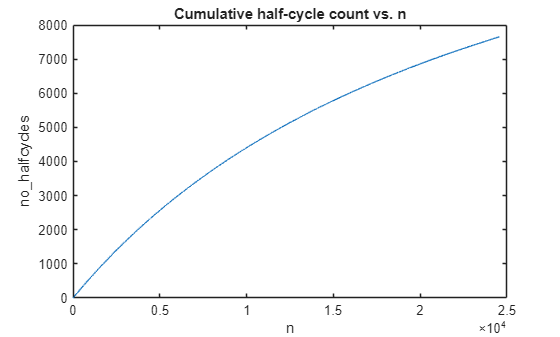

%% Step 5:
no_halfcycles = cumsum(signchanges);

plot(n, no_halfcycles)
xlabel('n')
ylabel('no\_halfcycles')
title('Cumulative half-cycle count vs. n')

%% Step 6:
X = n/N;
Y = 2*n./no_halfcycles;

%% Step 7:
half = floor(N/2)+1 : N;

p = polyfit(X(half), Y(half), 1);   % p = [slope, intercept]
b = p(1);
a = p(2);

%% Step 8:
my_v = n./(a + b*(n/N));
my_chirp = cos(2*pi*my_v);

save LABHW_04 my_chirp
